## Bifurcation Diagram Calculator

**Purpose:** Find all the steady states for 100 different models with varying *a* parameter values. 

**Method: **Uses Newton's method on a range of initial guesses that are within predetermined bounds for where the steady states could reside. All unique steady state are stored and graphed against a values to create a bifurcation diagram.

**Run Time:** 5 Minutes

clear;

%Make Parameters Global so that a range of DEs can be considered
global a;
global i;

%Mesh a & create storage for steady states
a = linspace(.02, .03,100);
ss = zeros(4,100);

%Create Mesh for initial guesses that are bounded within [0,1.5]
x0s = linspace(0,1.5,1000);

%For Each Model
for i = 1: length(a)
    
    %Zeros Storage
    zs = zeros(1000,1);
    
    %Try Newtons on each of our x0s. 
    for j = 1: length(zs)
        
        zs(j) = fzero(@DE, x0s(j));
    end
    
    %Store unique Zeros
    zs = uniquetol(zs,.001);
    
    %Snap Approximations of 0 to 0. Determining what was and wasn't a 
    %steady state at x = 0 was done by bounding the distance between 
    %the steady state values.
    for j = 1: length(zs)
        
        %If any of our steady states are actually an approximation to 0,
        %snap that value to 0
        if(zs(j) < 0 && zs(j) > -.15)
            zs(j) = 0;
        end
    end
    
    %Store Steady State Values
    for j = 1: length(zs)
        
        ss(j,i) = zs(j);
    end
    
end

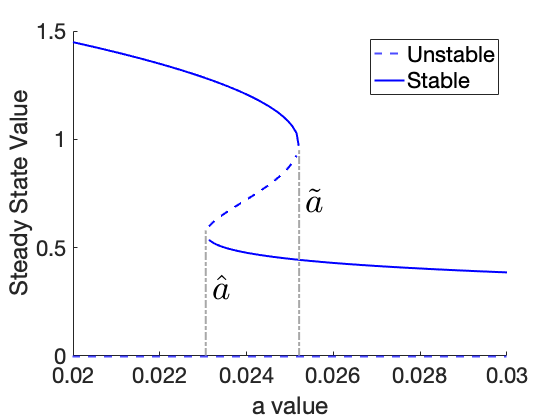

%Plotting

%Sort For Plotting Purposes
for i = length(ss)
    
    ss(:,i) = sort(ss(:,i));
end

%There Exists an unstable steady state across 0. 
figure;
yline(0,'b--','LineWidth',2);
hold on;

%First Solid Blue Line + a Joint Fix Between Data
p1 = [ss(2,1:31) ss(4,32:52)];
p1 = [p1 .97];
a1 = [a(1:52) .0252001];
plot(a1,p1,'b','LineWidth',2);
hold on;

%Plot Unstable States
plot(a(32:52), ss(3,32:52),'b--','LineWidth',2);
hold on;

%Plot rest of solid line
plot(a(32:52),ss(2,32:52),'b','LineWidth',2);
hold on;
p4 = [ss(2,52:end-1) ss(4,end)];
plot(a(52:end),p4,'b','LineWidth',2);
hold on;

%Draw a hat and a tilde
line([.0230588 0.0230588], [0 .58], 'color', [.66 .66 .66],'linewidth',2,'linestyle','-.');
hold on;
line([0.0252092 0.0252092], [0 .95], 'color',[.66 .66 .66],'linewidth',2,'linestyle','-.');
hold on;

%Make Fig Pretty
xlabel('a value',"FontSize",22);
ylabel('Steady State Value',"FontSize",22);
legend('Unstable','Stable',"FontSize",22);
set(gca,'FontSize',22);
text(.0232,.3,{'$\hat{a}$'},'Interpreter',"latex","FontSize",35);
text(.02535,.7,{'$\tilde{a}$'},'Interpreter',"latex","FontSize",35);

**Our Differential Equation**

function f = DE(x)

global a;
global i;

%Parameters
r = .05;
K = 2;
h = .38;
q = 5;

f = r * x * (1-(x/K)) - (a(i)*x^(q))/(x^(q) + h^(q));

end
